# EG-247 Signals and Systems: Lab 01: Elementary Signals

This script file demonstrates the use of the `heaviside` and `dirac` functions. To run the code select the commands in the cells.

This is also an example of the use of the publishing feature of MATLAB.

## The Unit Step Function

In the notes we define the unit step function as


$${u_0}(t) = \left\{ {\begin{array}{*{20}{c}}
{0\quad t < 0}\\
{1\quad t > 0}
\end{array}} \right.$$


In MATLAB the unit step is defined using the `heaviside` function

doc heaviside

We can thus define and plot the unit step $u_0(t)$ with the command

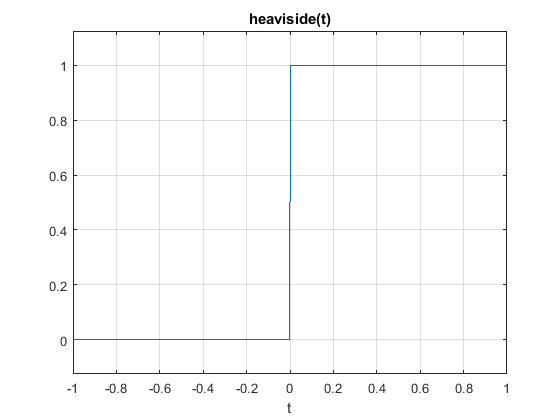

syms t;
heaviside(t);
ezplot(ans,[-1,1]),grid

If we are only interested in the value of the function at a particular instant of time we can pass a number as the argument:

[heaviside(-1),heaviside(0),heaviside(1)]

ans =          0    0.5000    1.0000


## Note that `heaviside(0)` returns the value $1/2$ which is not

mathematically correct. The unit step function $u_o(t)$ is undefined at $t=0$.

The basic signal operations work as you'd expect

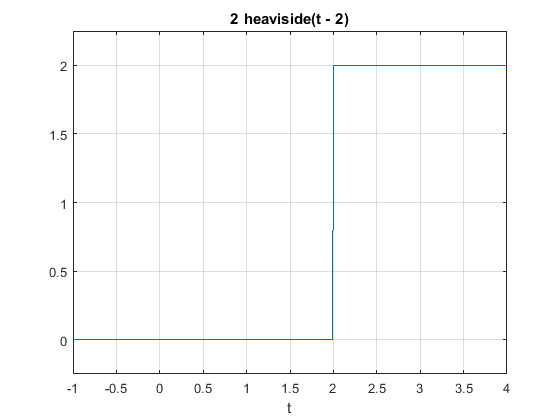

A = 2; T = 2;
v1 = A * heaviside(t - T);
ezplot(v1, [-1, 4]), grid

## Part 1

To validate Figure 1.8 in the textbook Karris (page 1-4) use the `heaviside` and `ezplot` functions to plot each of the following:

- 
$$-Au_0(t)$$


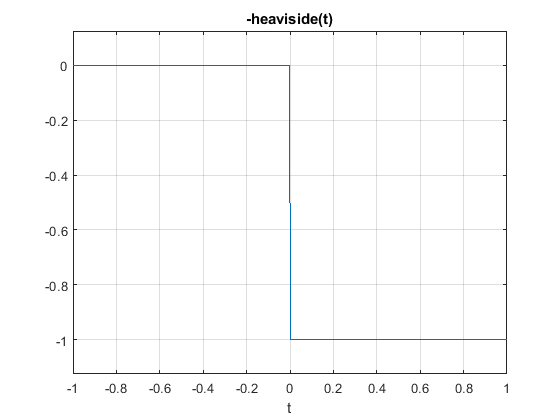

syms t;
n=heaviside(t);
ezplot(-n,[-1,1]),grid

- 
$$-Au_0(t-T)$$


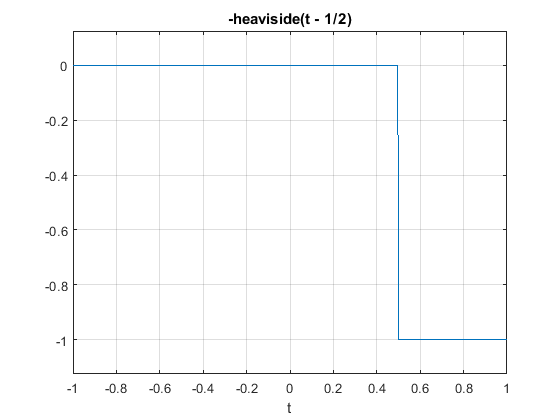

syms t;
T = 0.5;
n=heaviside(t-T);
ezplot(-n,[-1,1]),grid

- 
$$-Au_0(t+T)$$


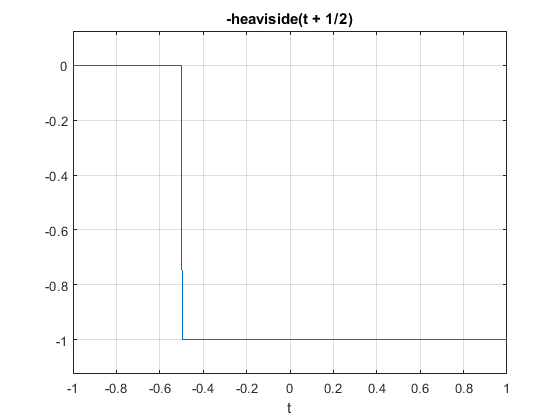

syms t;
T = 0.5;
n=heaviside(t+T);
ezplot(-n,[-1,1]),grid

- 
$$Au_0(-t)$$


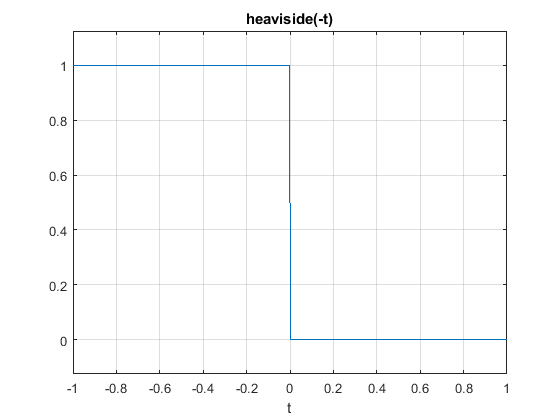

syms t;
n=heaviside(-t);
ezplot(n,[-1,1]),grid

- 
$$Au_0(-t+T)$$


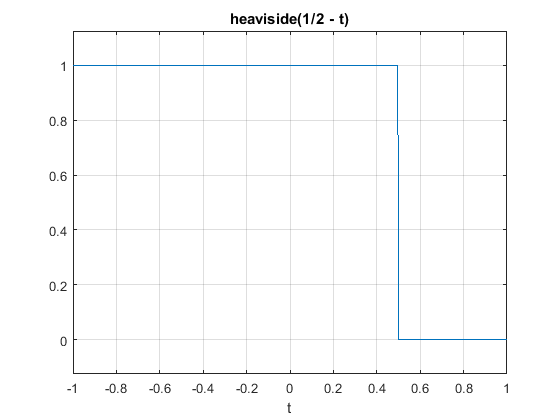

syms t;
T = 0.5;
n=heaviside(-t+T);
ezplot(n,[-1,1]),grid

- 
$$Au_0(-t-T)$$


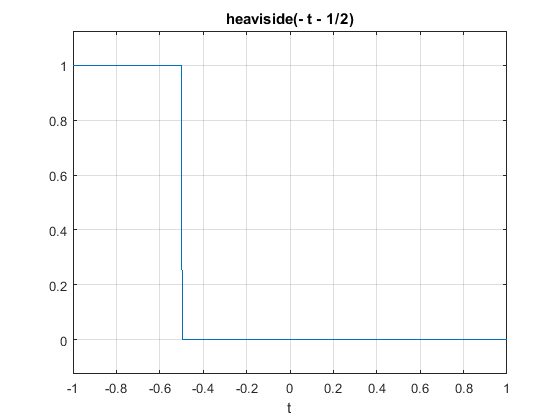

syms t;
T = 0.5;
n=heaviside(-t-T);
ezplot(n,[-1,1]),grid

- 
$$-Au_0(-t)$$


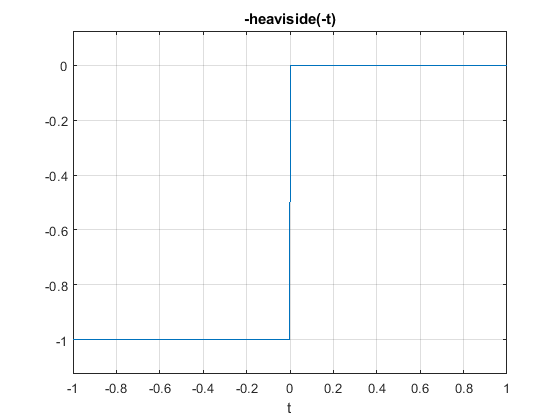

syms t;
T = 0.5;
n=heaviside(-t);
ezplot(-n,[-1,1]),grid

- 
$$-Au_0(-t+T)$$


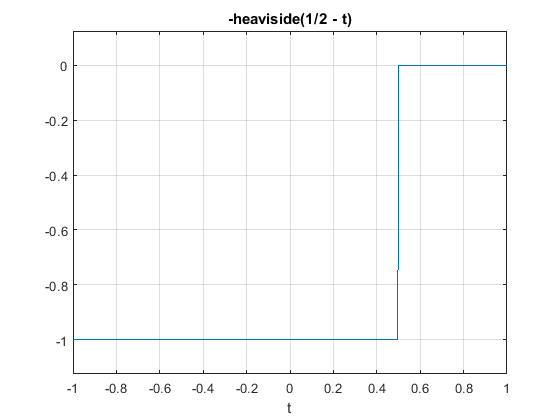

syms t;
T = 0.5;
n=heaviside(-t+T);
ezplot(-n,[-1,1]),grid

- 
$$-Au_0(-t-T)$$


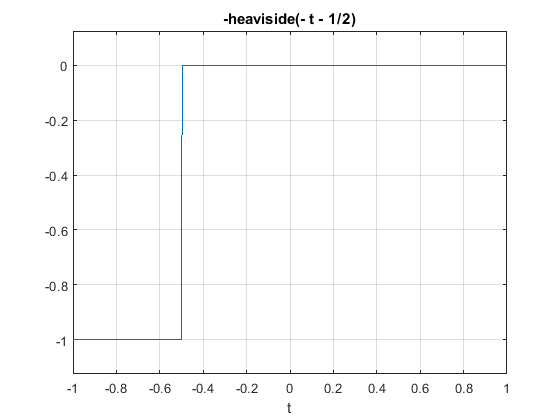

syms t;
T = 0.5;
n=heaviside(-t-T);
ezplot(-n,[-1,1]),grid

## Part 2

Use the `heaviside` and `ezplot` functionshow that $u_0(t) - u_0(t - 1)$ represents the rectangular pulse shown in Figure 1.9 (a) in the textbook.

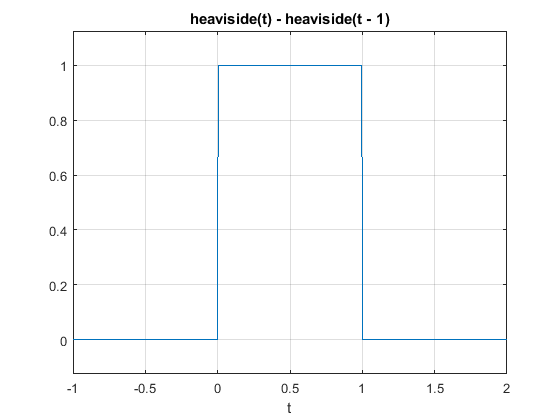

syms t;
n = heaviside(t);
x = heaviside(t-1);
f = n - x;
ezplot(f,[-1,2]),grid

## Part 3

Use the `heaviside` and `ezplot` functions to validate equations 1.13, 1.14, 1.17 and 1.18 in the textbook.

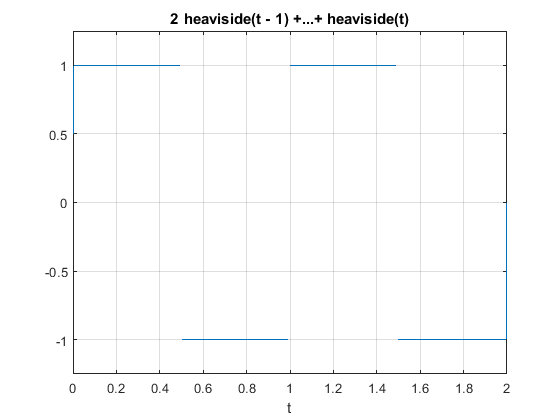

%Equation 1.13 where A = 1 T = 0.5
x = heaviside(t-T);
x2 = heaviside(t-2*T);
x3 = heaviside(t-3*T);
x4 = heaviside(t-4*T);
v = (heaviside(t)- 2*x + 2*x2 - 2*x3 + 2*x4);
ezplot(v,[0,2]),grid

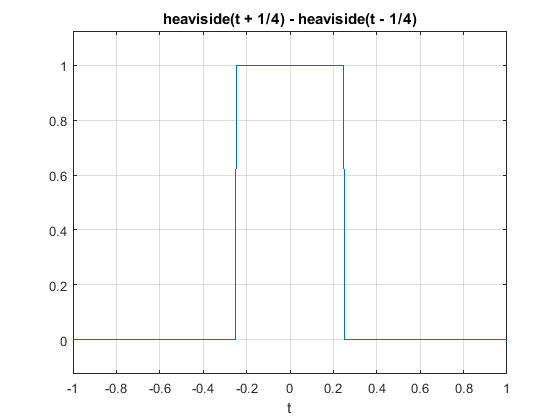


%Equation 1.14 where A = 1 T = 0.5
r1 = heaviside(t+(T/2));
r2 = heaviside(t-(T/2));
i = (r1 - r2);
ezplot(i,[-1,1]),grid

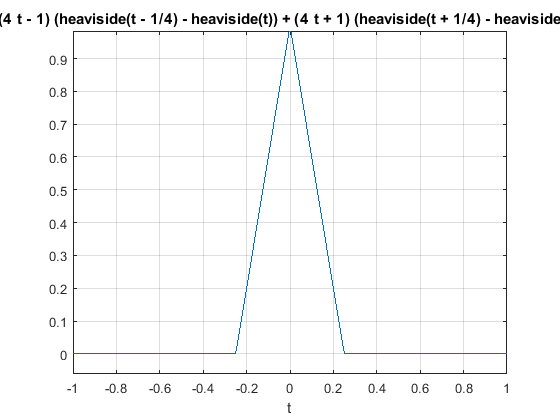


%Equation 1.17 where A = 1 T = 0.5
v2 = ((2/T)*t+1)*(r1-heaviside(t))+(-(2/T)*t+1)*(heaviside(t)-r2);
ezplot(v2,[-1,1]),grid

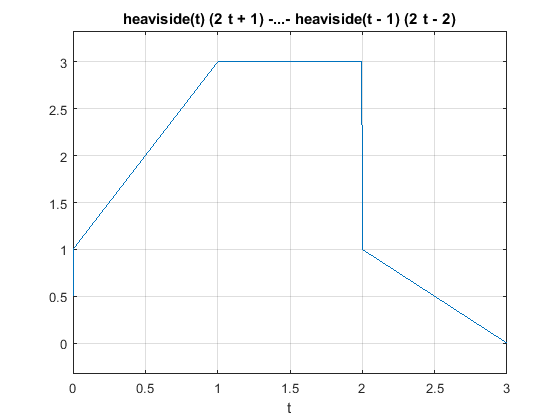


%Equation 1.18 where A = 1 T = 0.5
v3 = ((2*t)+1)*heaviside(t) - 2*(t-1)*heaviside(t-1) - t*heaviside(t-2) + (t-3)*heaviside(t-3);
ezplot(v3,[0,3]),grid

## The Ramp Function

The integral of the **unit step** function is the **ramp function**


$$u_1(t) = \int_{-\infty}^{t} u_0(\tau)d\tau$$


Gives


$${u_1}(t) = \left\{ {\begin{array}{*{20}{c}}
{0\quad t < 0}\\
{t\quad t > 0}
\end{array}} \right. = t{u_0}(t)$$


To verify this result:

syms tau
u1 = int(heaviside(tau),-inf, t)

$$u1 = \frac{t\,\left(\mathrm{sign}\left(t\right)+1\right)}{2}$$

Plot the ramp function

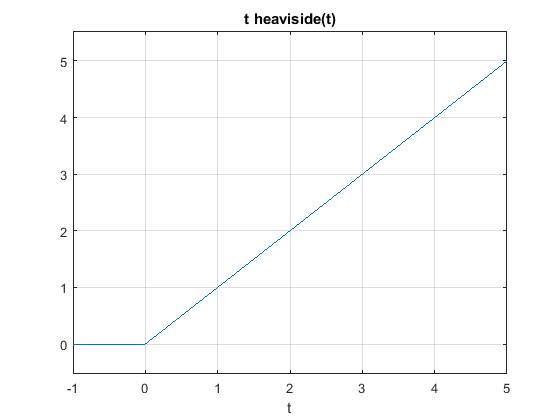

ezplot(t * heaviside(t), [-1,5]), grid

%

## Part 4

Use `ezplot` to plot $u_2(t)$ and $u_3(t)$ as defined on Page 1-10 of the textbook.

syms tau
u1 = int(heaviside(tau),-inf, t)

$$u1 = \frac{t\,\left(\mathrm{sign}\left(t\right)+1\right)}{2}$$

u2 = t.^2*heaviside(1)

$$u2 = t^{2}$$

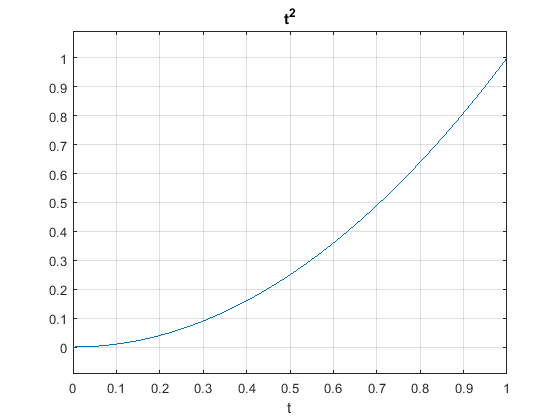

ezplot(u2,[0,1]),grid

u3 = t.^3*heaviside(1)

$$u3 = t^{3}$$

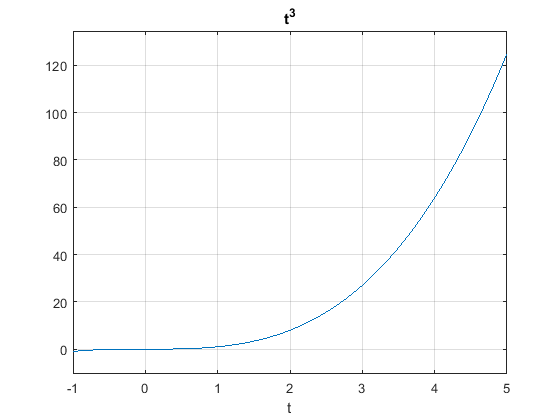

ezplot(u3,[-1,5]),grid

## The Dirac Delta Function

$\delta(t)$ is the derivative of $u_0(t)$

diff(heaviside(t),t)

$$ans = \delta (t)$$

It's not easy to plot the dirac delta function. We have to cheat a little

td = [-1,0,1]; delta = [0,1,0];
stem(td,delta)

## Part 5

Use Matlab to solve Examples 1.8 and 1.9 from the textbook. Don't Forget to Save Your Work!

%Example 1.8
%a

3*t^4*diff(heaviside(t-1))

$$ans = 3\,t^{4}\,\delta (t-1)$$


%b
int(t*diff(heaviside(t-2)),-inf,inf)

$$ans = 2$$


%c
t^2*diff(diff(heaviside(t-3)))

$$ans = t^{2}\,\delta^{\prime }(t-3)$$

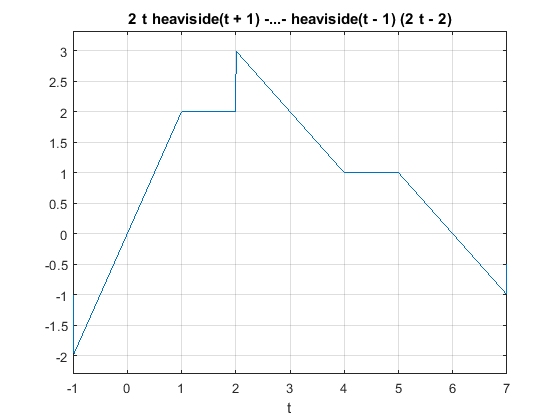


%Example 1.9
%a
v = 2*t*heaviside(t+1) + (-2*t+2)*heaviside(t-1) + (-t+3)*heaviside(t-2) + (t-4)*heaviside(t-4) + (-t+5)*heaviside(t-5) + (t-6)*heaviside(t-7);
ezplot(v,[-1,7]),grid

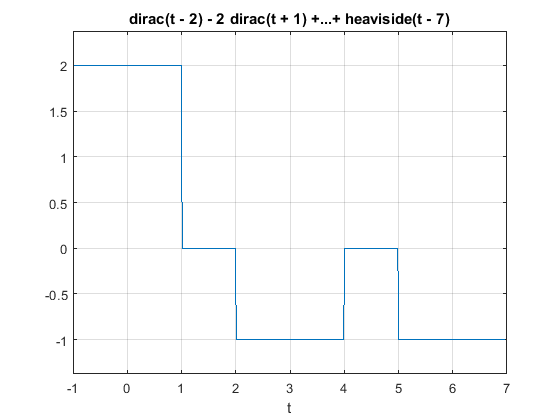


%b
dv = 2*heaviside(t+1) - 2*diff(heaviside(t+1)) - 2*heaviside(t-1) - heaviside(t-2) + diff(heaviside(t-2)) + heaviside(t-4) - heaviside(t-5) + heaviside(t-7) + diff(heaviside(t-7));
ezplot(dv,[-1,7]),grid